# Spike Triggered Averaging (STA) 

STA is a common method to determine the relationship between stimuli and neural response. It is frequently used in receptive field mapping. 

Essentialy what we do in this type of analysis is averaging stimulus blocks prior to a spike.

Consider a case in which we want to map receptive field of a neuron in retina for example. Each stimulus is presented for 1000 ms and the luminance of each pixel changes every milisecond. Here is milisecond resolusion of screen luminance for a single trial.

stimNum = 1000;
stim = randn(20,20,stimNum);

% Plotting the 5th stimulus
figure;
imagesc(stim(:,:,5)), colormap gray;
title('Stimulus sequence')

Let's a particular neuron's RF be at upper right of the screen. So whenever the luminance of the screen at that location passes a thereshold the neurons fires a spike.

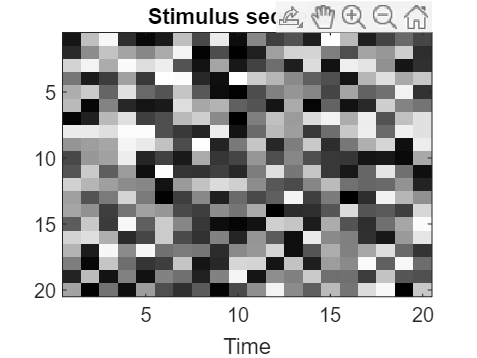

lumThershold = 7;
spikes = zeros(1,stimNum);
stimIdx = [];
for stim_i = 1:stimNum
    if sum(stim(5:8,12:16,stim_i),'all') > lumThershold

        spikes(1,stim_i) = 1;

ans = 46.9546

        stimIdx = [stimIdx stim_i]
    end
end

% plotting spike train


% plotting RF

RF = sum(stim(:,:,stimIdx),3);
imagesc(RF), colormap gray

Invalid expression. Check for missing multiplication operator, missing or unbalanced delimiters, or other syntax error. To
construct matrices, use brackets instead of parentheses.